# Week 6 Help – Plotting

clear; clc; close all;

## Setting Up Plotting Data

Let's set up some data to plot. Below is a function that given some array of time values (t), computes the x and y coordinates of some equation. Additionally, a constant term is in the equation.

t = 0:0.01:37.7;

[x1,y1] = plotCurve(t, 4);
[x2,y2] = plotCurve(t, 2);

[xs,ys] = plotCurve(0:1:37, 4);

## Making Plots in MATLAB

Initialize a figure by calling the MATLAB function "figure()". You can pass additional input arguments into the figure function as per the MATLAB help documentation: "help figure".

**Use "hold on" and "hold off" to tell MATLAB you want to include multiple plots on a single figure. The plots need to be within the hold lines as seen below:**

figure();

hold on;
plot(x1,y1, 'Linewidth',2.0, 'LineStyle','--','Color',[1 0 1]);
plot(x2,y2);
scatter(xs, ys, 50, 'filled', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'r');
hold off;

- The first plot call will create a line that is magenta in color because of the R G B values: [1 0 1]. It is a dashed line that has a thickness of 2.0 font.

- The second plot is a MATLAB defaults line (if no custom styles are specified MATLAB has plot defaults).

- The third plot is a scatter plot. The scatter points have a size of 50 units, they are filled (as opposed to open), the fill color is cyan ('c'), and the point edge color is red ('r').

We can turn on the x/y grid, make a box around our plot, and make sure our axes scaling is identical with the following lines of code:

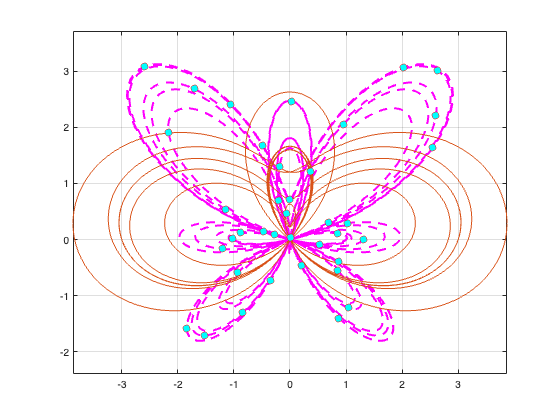

grid on; 
box on; 
axis equal;

## Adding Axes Labels, a Title, and a Legend

We can add axis labels, and a title as shown below:

xlabel('x-axis','Fontsize', 20, 'FontWeight', 'bold');
ylabel('y-axis','FontSize', 20, 'FontWeight', 'bold');
title('My Plot Title','FontSize',20,'Color','b');

We can add a plot legend to distinguish the individual plots.

legend({'First Curve','Second Curve','Scatter Points'}, ...
    'FontSize', 16, 'Location','southoutside', 'Interpreter','latex');

This legend contains entries "First Curve," "Second Curve," and "Scatter Points" which follows the order we plotted them in our code. A custom fontsize is set and the text interpreter "Latex" is used. We can change the location of the legend so it doesn't overlay ontop of our plots.

## Adding to the Figure

What if I want to plot something else on my figure even after I created it? I can reuse "hold on" and "hold off" as follows:

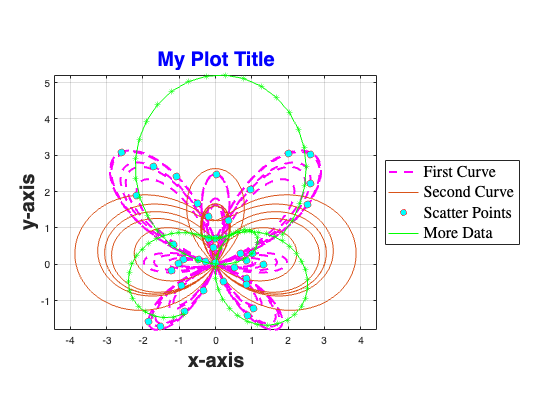

t = 10:0.1:20;
[xmore, ymore] = plotCurve(t, 1.5);

% Still the same figure from above ^^^^
hold on;
plot(xmore, ymore, 'Color', 'g', 'Marker','*'); % Plots line and scatter points
hold off;

% Updated Legend
legend({'First Curve','Second Curve','Scatter Points','More Data'}, ...
    'FontSize', 16, 'Location','eastoutside', 'Interpreter','latex');

## Data Generation Function

Remember, functions are always defined at the end of the MATLAB script!

function [x,y] = plotCurve(t, c)
    s1 = c;
    s2 = c*3;
    x  = sin(t).*( exp(cos(t)) - 2*cos(s1*t) - sin(t/s2).^5 );
    y  = cos(t).*( exp(cos(t)) - 2*cos(s1*t) - sin(t/s2).^5 );
end